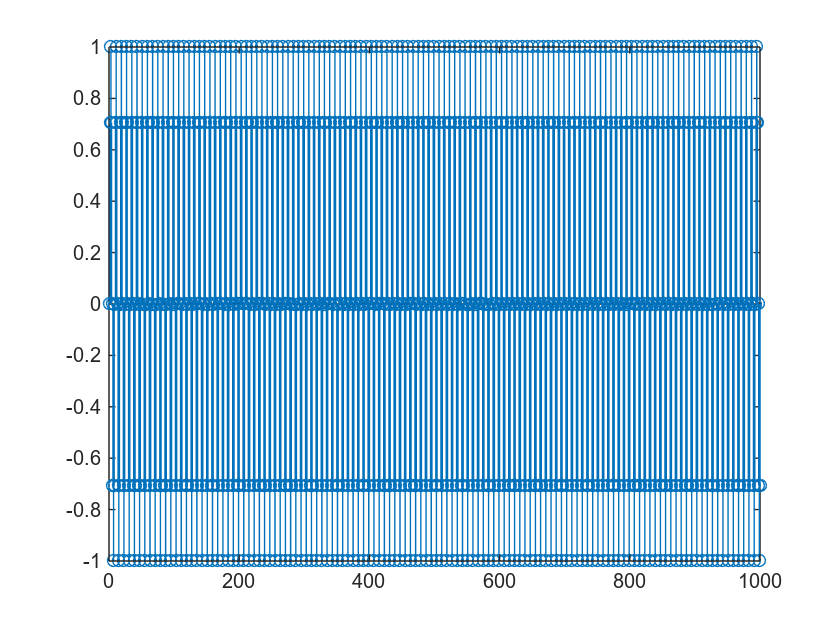

% TP1 signals and filters
% 2024/11/14
% Lyu Jianming 22022100033

clear 
close all

% initialisation
Fe = 8000;
Te = 1/Fe;
f0 = 1000;      % Fe >= 2f0
N_ech = 1000;
n = 0 : Te : (N_ech-1)*Te;      % 每个采样点间隔Te
sn = sin(2*pi*f0*n);
stem(sn)

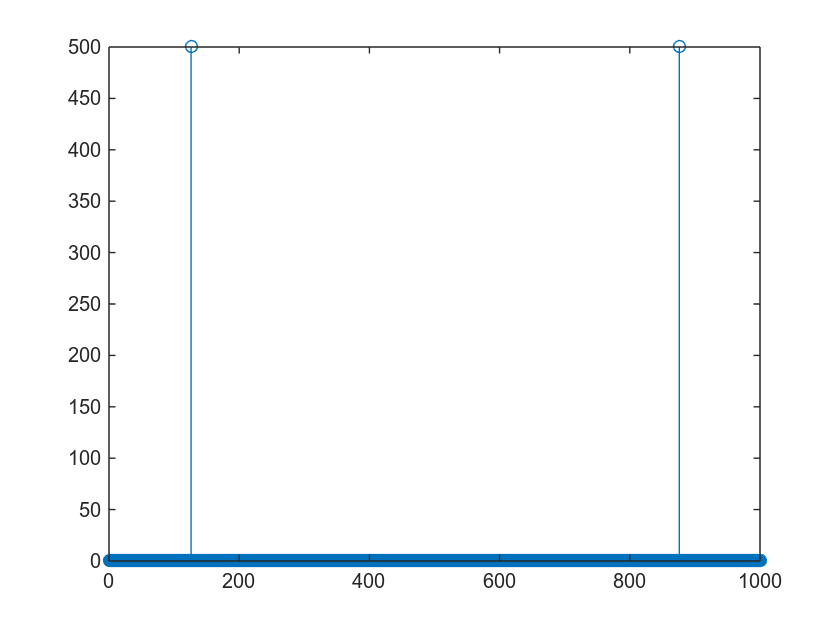

stem(abs(fft(sn)))

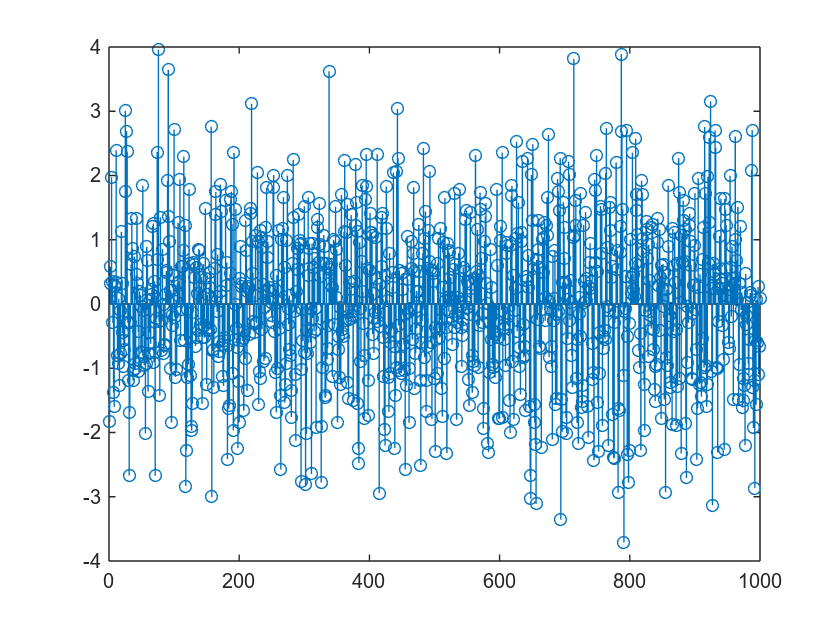

bn = randn(1, N_ech);       % bruit => 1 x 1000
xn = sn + bn;
stem(xn)

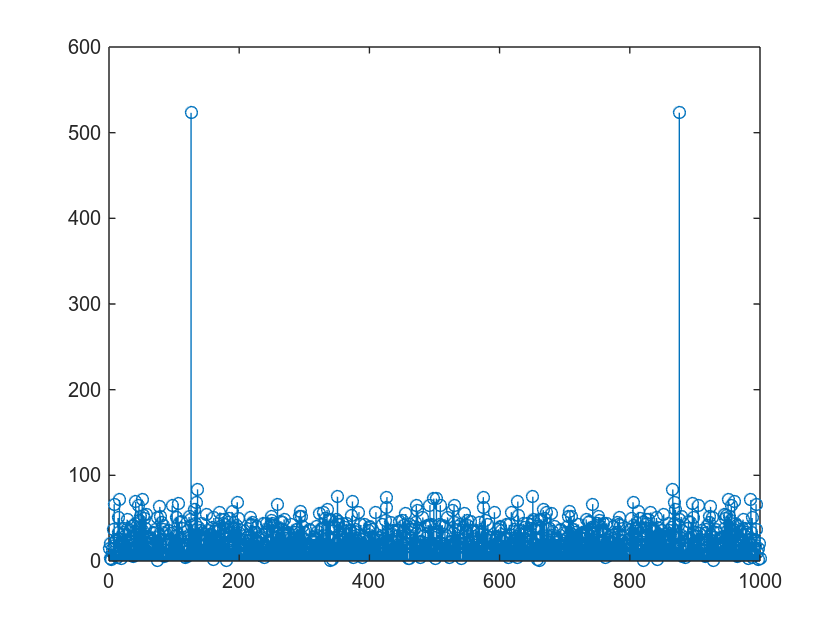

stem(abs(fft(xn)))

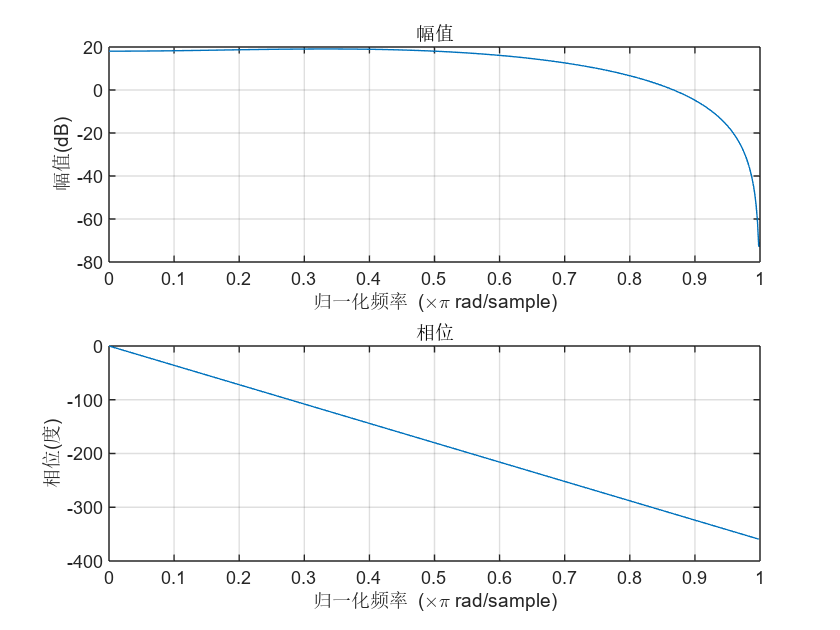

% H
H0_num = [-1, 2, 6, 2, -1];
H0_den = 1;         % denominateur = 1 => stable
H1_num = [1, -2, 1];
H1_den = 1;
freqz(H0_num, H0_den)       % passe bas; 相位：phi(f) = -(L-1)*pi*f/fe

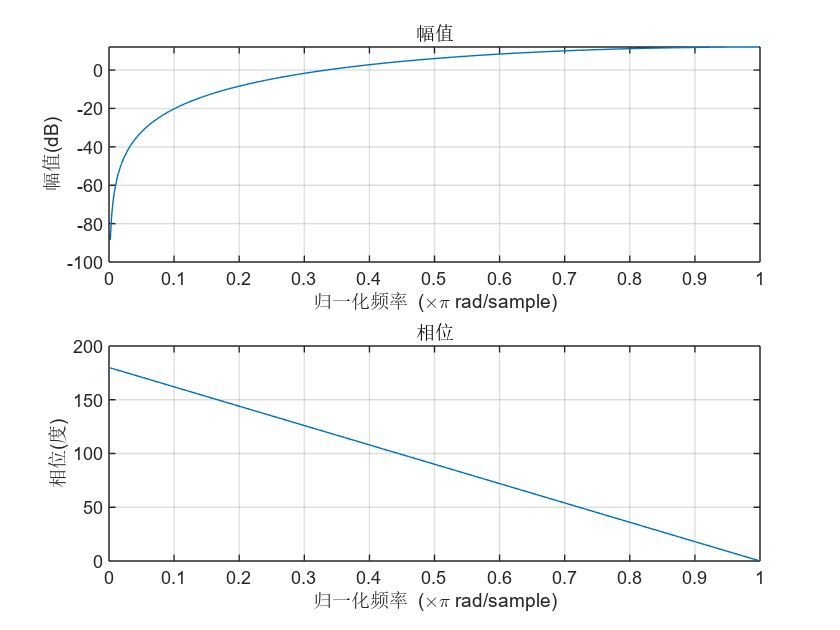

freqz(H1_num, H1_den)       % passe haut

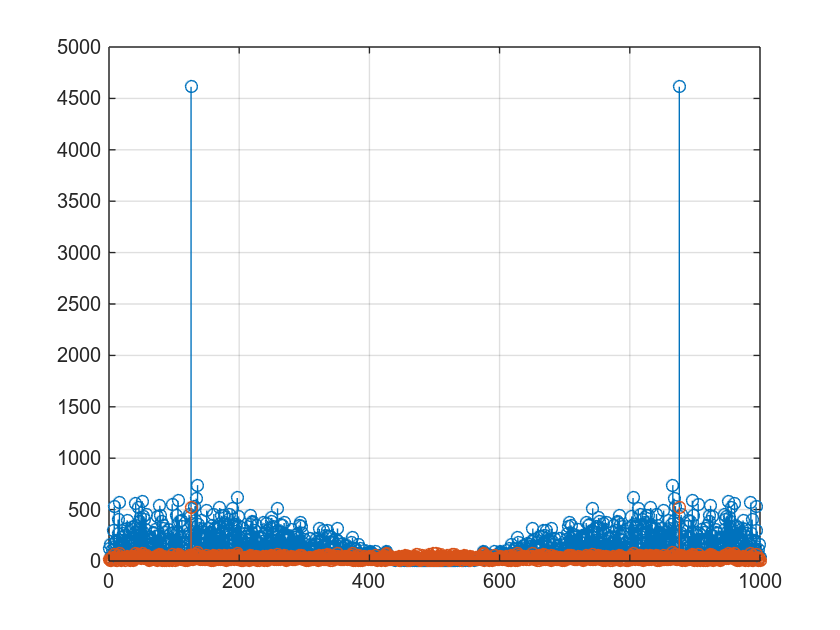

% calcule u0 et u1
u0 = filter(H0_num, H0_den, xn);        % 对输入信号xn进行滤波
u1 = filter(H1_num, H1_den, xn);

% u0
stem(abs(fft(u0)))      % 蓝色的是u0（滤波后）=> passe bas
hold on 
stem(abs(fft(xn)))      % xn是滤波前的输入信号
grid
hold off

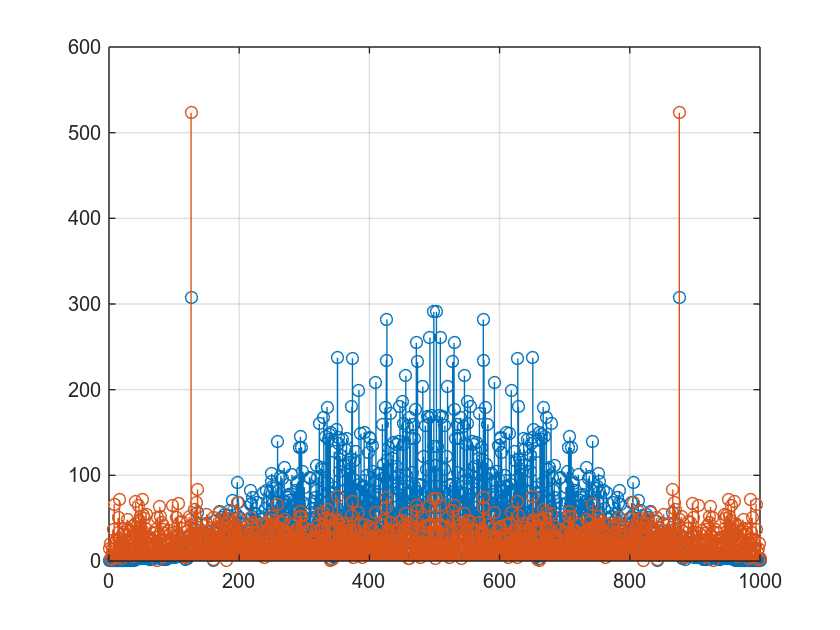


% u1
stem(abs(fft(u1)))      % 蓝色的是u1 => passe haut
hold on
stem(abs(fft(xn)))
grid
hold off

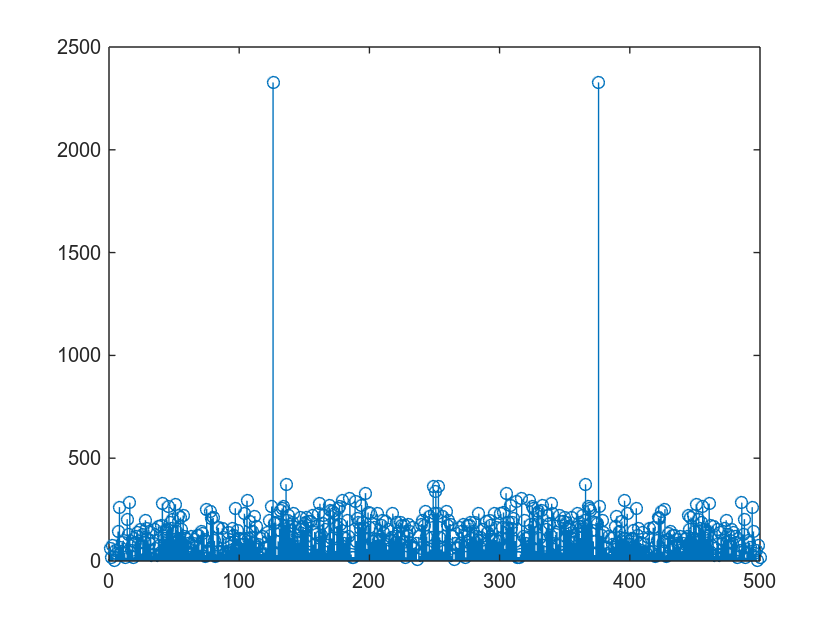

% calcule de v0 et v1
v0 = downsample(u0, 2);     % sous echantillonage d'ordre 2
v1 = downsample(u1, 2);
stem(abs(fft(v0)))

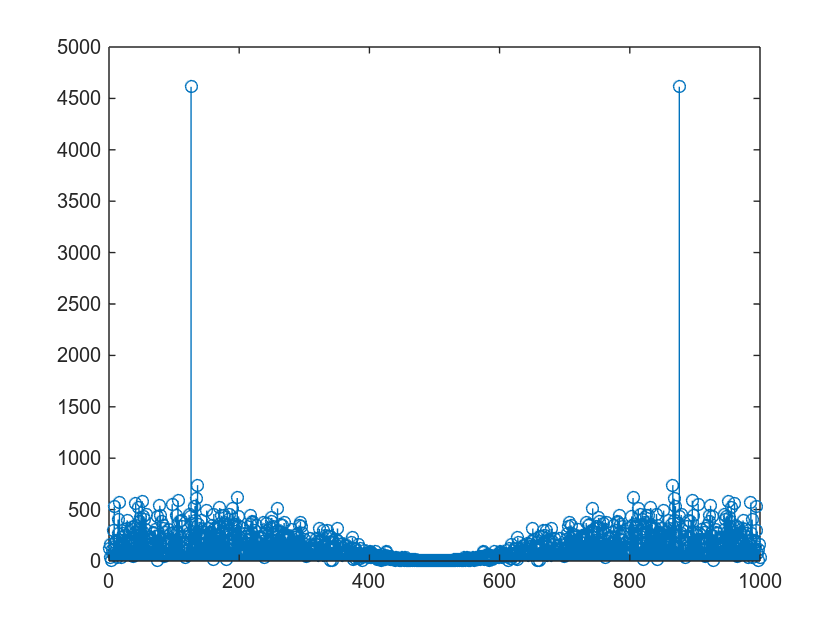

stem(abs(fft(u0)))

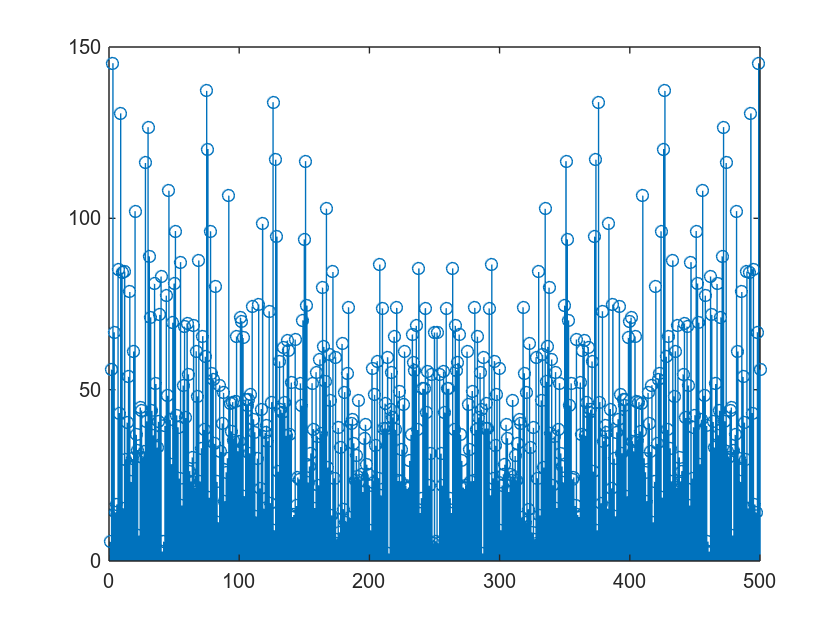

stem(abs(fft(v1)))

对一个信号进行降采样（downsample），例如以2阶降采样（即每隔一个样本取一个）后，其傅里叶变换频谱会发生以下变化：

- 频谱压缩：降采样会导致频谱在频率轴上的压缩。具体来说，如果原始采样率为 Fe，在2阶降采样后，新的采样率变为 Fe/2。这意味着在频率轴上，信号的频谱被压缩到原来的一半。

- 混叠现象：如果信号在降采样之前未经过适当的低通滤波（即抗混叠滤波）处理，频谱中的高频成分可能会折叠到低频范围内，造成混叠。这是因为降采样后新的采样率变为 Fe/2，而根据奈奎斯特定理，频率超过 Fe�/4 的成分会出现混叠。

为什么会发生这样的变化？

- 频谱压缩：降采样从时域的角度上减少了采样点的数量，这意味着其在频域上也会体现出某种形式的压缩。频率分辨率下降，新频谱范围变为 [0, Fe/2]，与原始频谱 [0, Fe�] 比较，相当于压缩到一半。

- 混叠现象：当信号含有超过新奈奎斯特频率（即 Fe�/4）的频率成分时，这些高频成分无法在降采样后的采样率下被正确表示，导致它们折叠回低频范围。因此，进行降采样之前，通常需要使用低通滤波器滤除高于新奈奎斯特频率的信号成分，以避免混叠。